% Clear workspace and command window
clear;
clc;

% FOR DESKTOP: Read data from the Excel file
% data = readtable('Rainfall_Loggers_monthly_SUM.csv');
data = readtable('Rainfall_MM_Loggers_monthly_SUM.csv');

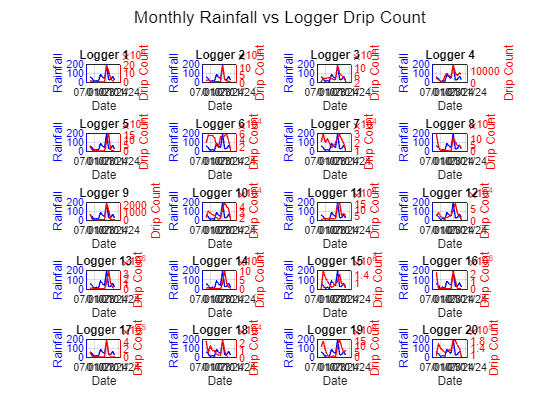


% Extract dates, rainfall, and drip count data
dates = data{:, 1}; %time is in column 1
rainfall = data{:, 2}; %rainfall is in column 2
drip_count = data{:, 3:22}; % Drip count is in columns 3 to 22

% Create a figure with 20 subplots
figure;

for i = 1:20
    subplot(5,4,i);
    
    % Plot rainfall
    yyaxis left;
    plot(dates, rainfall, 'b');
    ylabel('Rainfall');
    xlabel('Date');
    datetick('x', 'mm/dd/yy', 'keepticks');
    xticks=get(gca,'xtick');
    % Rotate x-axis labels for better readability
    xtickangle(0);
ax = gca; 
    ax.YAxis(1).Color = 'b'; 
    ax.YAxis(2).Color = 'r';

    % Adjust plot
    grid on;
    axis padded

    % Plot drip count
    yyaxis right;
    plot(dates, drip_count(:,i), 'r');
    %ylabel(['Drip Count ' num2str(i)]);
    ylabel('Drip Count');
    %legend ('Rainfall', 'Drip Count')
    % Adjust subplot title
    title(['Logger ' num2str(i)]);
sgtitle('Monthly Rainfall vs Logger Drip Count')
end